# Gaussian beam visualization

% Jonghwan Lee, Mar 2021

Parameters.  All lengths are in [m].

clear
E0 = 1.0;
lam = 500e-9;  % wavelength
zR = 5e-6;

k = 2*pi/lam

k = 1.2566e+07

Plot $w(z)$ and $R(z)$.

dz = lam/10;
z = -4*zR:dz:4*zR;  nz = length(z);

w0 = sqrt(2*zR/k)

w0 = 8.9206e-07

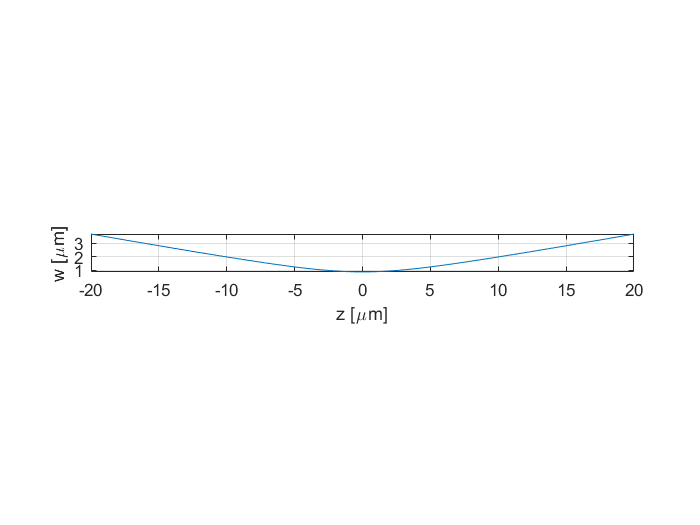

w = w0 * sqrt(1+(z/zR).^2);
R = z .* (1+(zR./z).^2);

figure
plot(z*1e6,w*1e6)
axis image
grid on
xlabel('z [\mum]')
ylabel('w [\mum]')

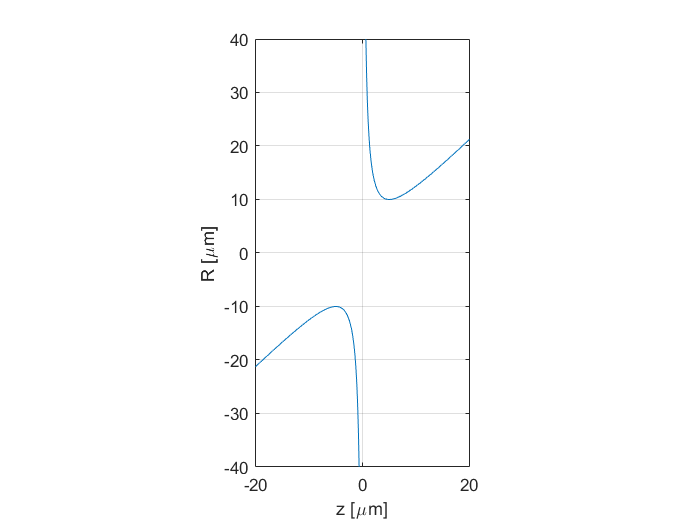


figure
plot(z*1e6,R*1e6)
axis image
ylim([-1 1]*max(z)*2*1e6)
grid on
xlabel('z [\mum]')
ylabel('R [\mum]')

Visualize $E(\rho,z)$ and its intensity.

rho = 0:dz:2*zR;  nrho = length(rho);
[grho,gz] = ndgrid(rho,z);
size(grho)

ans =    201   801


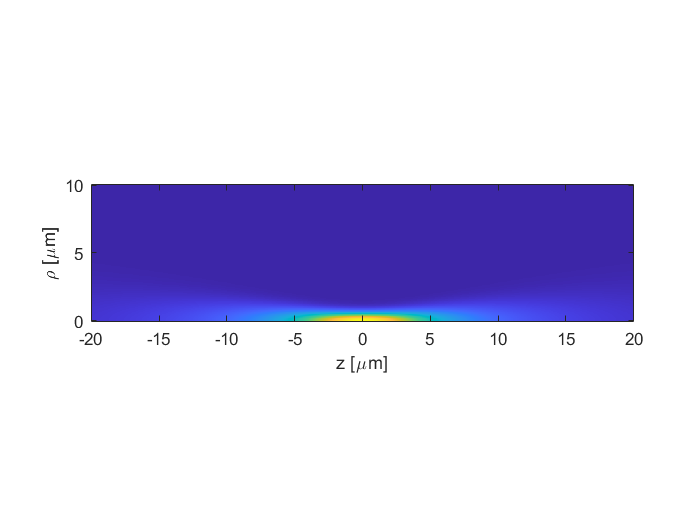


w = w0 * sqrt(1+(gz/zR).^2);  % 2D array
R = gz .* (1+(zR./gz).^2);
R(isnan(R)) = Inf;
zeta = atan(gz/zR);

E = E0/zR * w0 ./ w .* exp(-grho.^2 ./ w.^2) .* exp(1i*( k/2./R.*grho.^2 + pi/2 - zeta + k*z));
I = E .* conj(E);
I = abs(E).^2;

figure
imagesc(z*1e6,rho*1e6,I)  % no transpose because we want to use rho as the vertical axis
set(gca,'ydir','normal')
axis image
xlabel('z [\mum]')
ylabel('\rho [\mum]')

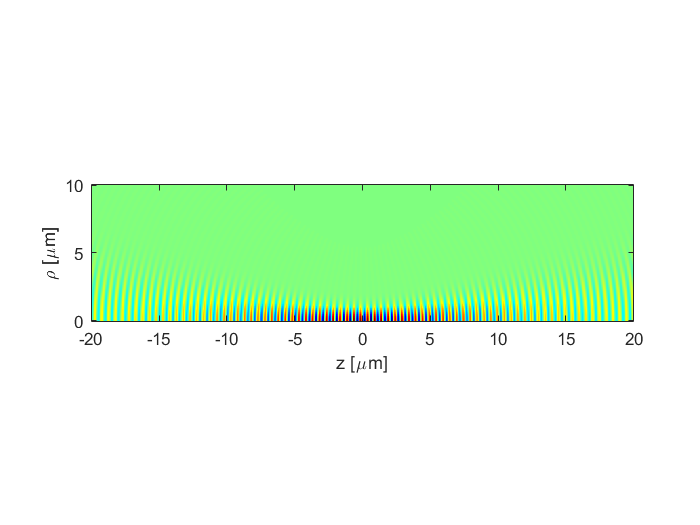


figure
colormap(jet)
imagesc(z*1e6,rho*1e6,real(E))
set(gca,'ydir','normal')
axis image
xlabel('z [\mum]')
ylabel('\rho [\mum]')

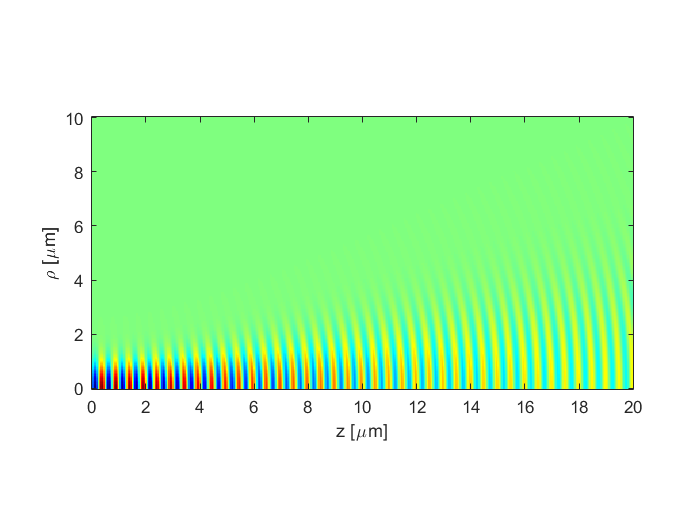

figure
colormap(jet)
imagesc(z(round(end/2):end)*1e6,rho*1e6,real(E(:,round(end/2):end)))
set(gca,'ydir','normal')
axis image
xlabel('z [\mum]')
ylabel('\rho [\mum]')

Plot $I(\rho)$ at several z positions.

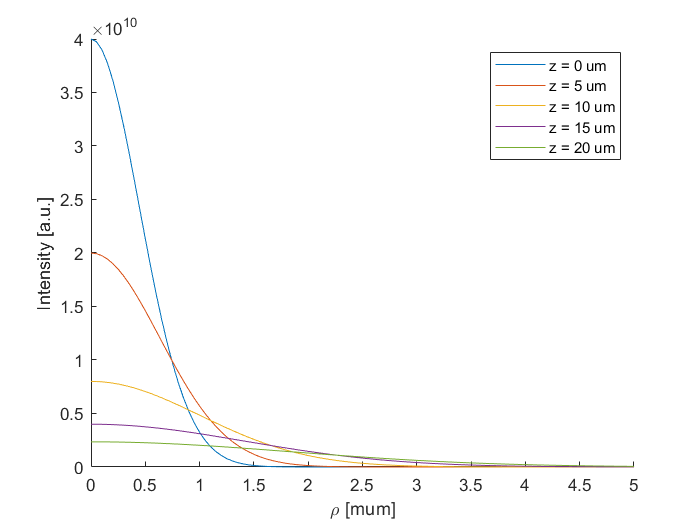

zs = (0:5e-6:max(z));  nzs = length(zs);

clr = lines(nzs);
figure
for iz=1:nzs
    z1 = zs(iz);
    [~,iz1] = min(abs(z-z1));
    line(rho*1e6,I(:,iz1),'color',clr(iz,:))    
end
xlim([0 5])
legend(compose('z = %g um',zs*1e6))
xlabel('\rho [mum]')
ylabel('Intensity [a.u.]')